PHYS 434

Lab 4 

Kuan-Wei Lee

Student#:1663855

Lab partner: Megam Miyasaki

**Problem 1**

In this problem we are looking at the data from a gamma-ray satellite orbiting in low Earth orbit. It takes a reading of the number of particles detected every 100 milliseconds, and is in an approximately 90 minute orbit. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays.

This data set has over 2 million data points and all the measurement(Solar phase, Earth longitude and cosmic ray counts) are taken once every 0.1 seconds. When I plot the cosmic ray counts agianst time over the entire data set, it looks like there's no big fluctuation, it is hard to tell if cosmic ray counts changes with time. However, when I plot cosmic ray counts against  earth longitude, it is clear that the counts is higher when the the satellite is at certain location relative to earth. The code below plot cosmic ray counts against time, solar phase and earth longitude.

clear all
close all
clc

h5disp("gammaray_lab4.h5")

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


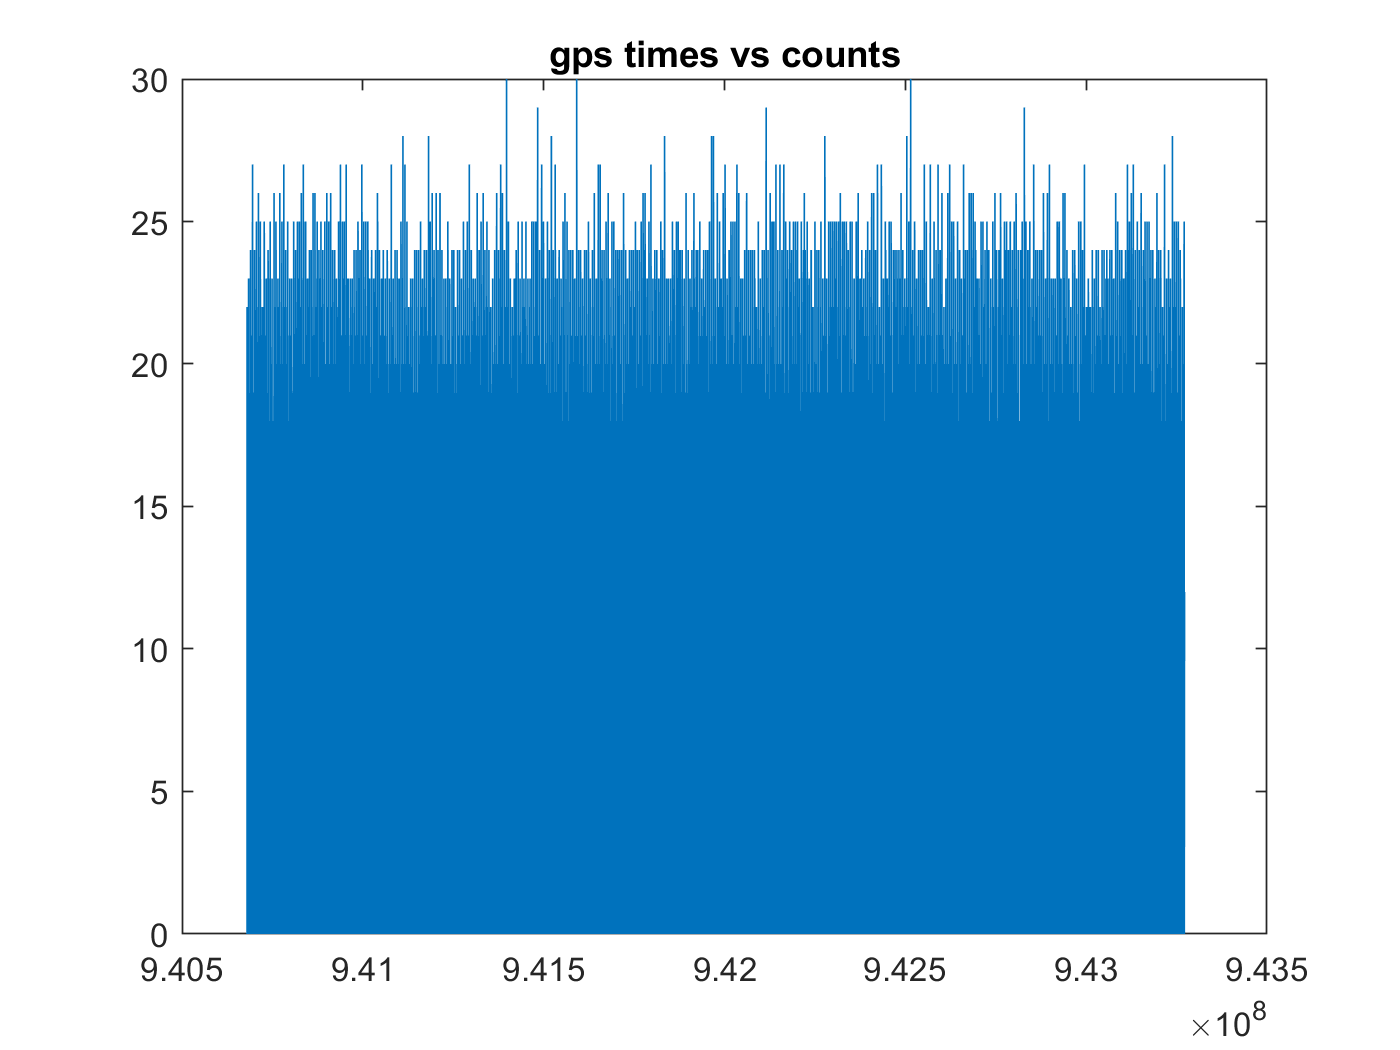

mydata = h5read("gammaray_lab4.h5",'/data');



plot(mydata(:,1),mydata(:,4))
title('gps times vs counts')

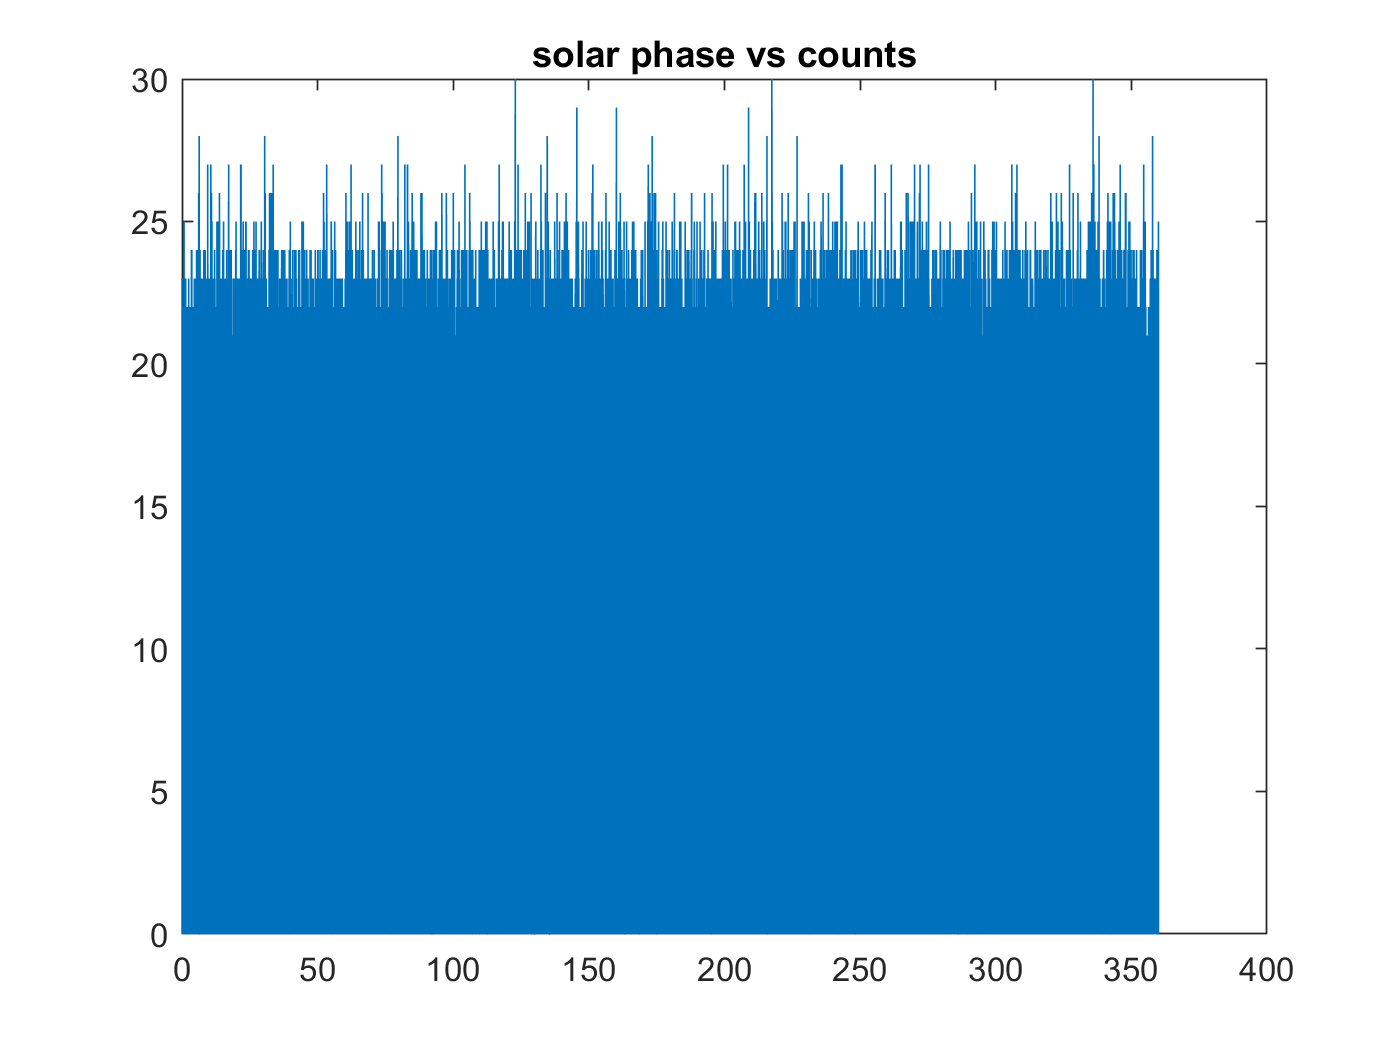


plot(mydata(:,2),mydata(:,4));
title('solar phase vs counts')

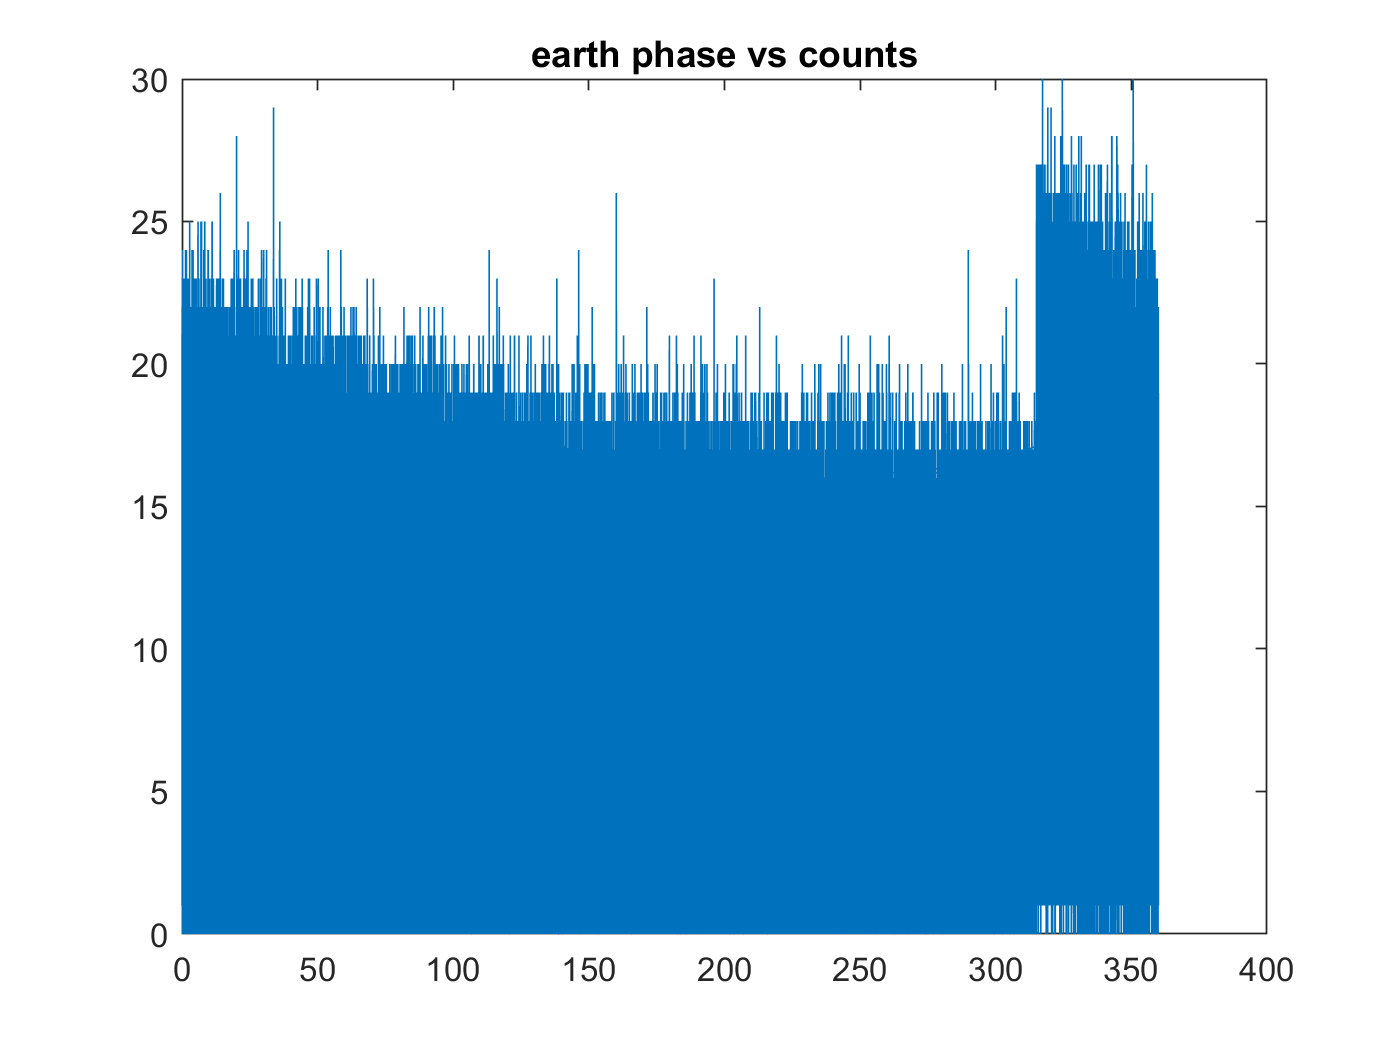


plot(mydata(:,3),mydata(:,4));
title('earth phase vs counts')

To investigate how the cosmic ray counts changes with time, I will only plot a small fraction of the data set because the counts could be varing in a small scale but does not fluctuate much in a large scale. First of all, I recognize that the orbiting period of the satellite is 90 minutes (5400 seconds), which correspond to 54000 data points(measurement is take once every 0.1 second). Therefore, I decided to plot only the first 54000*3 data points to see how the cosmic ray counts changes within 1 orbital period of the satellite.

The code below plot cosmic ray counts against time over the first 54000*3 points. It also plot the Earth longitude and solar phase against time to demonstrate that the angles oscillate between 0 and 360 degrees, which prove that we capture at least one orbital period of the satellite.

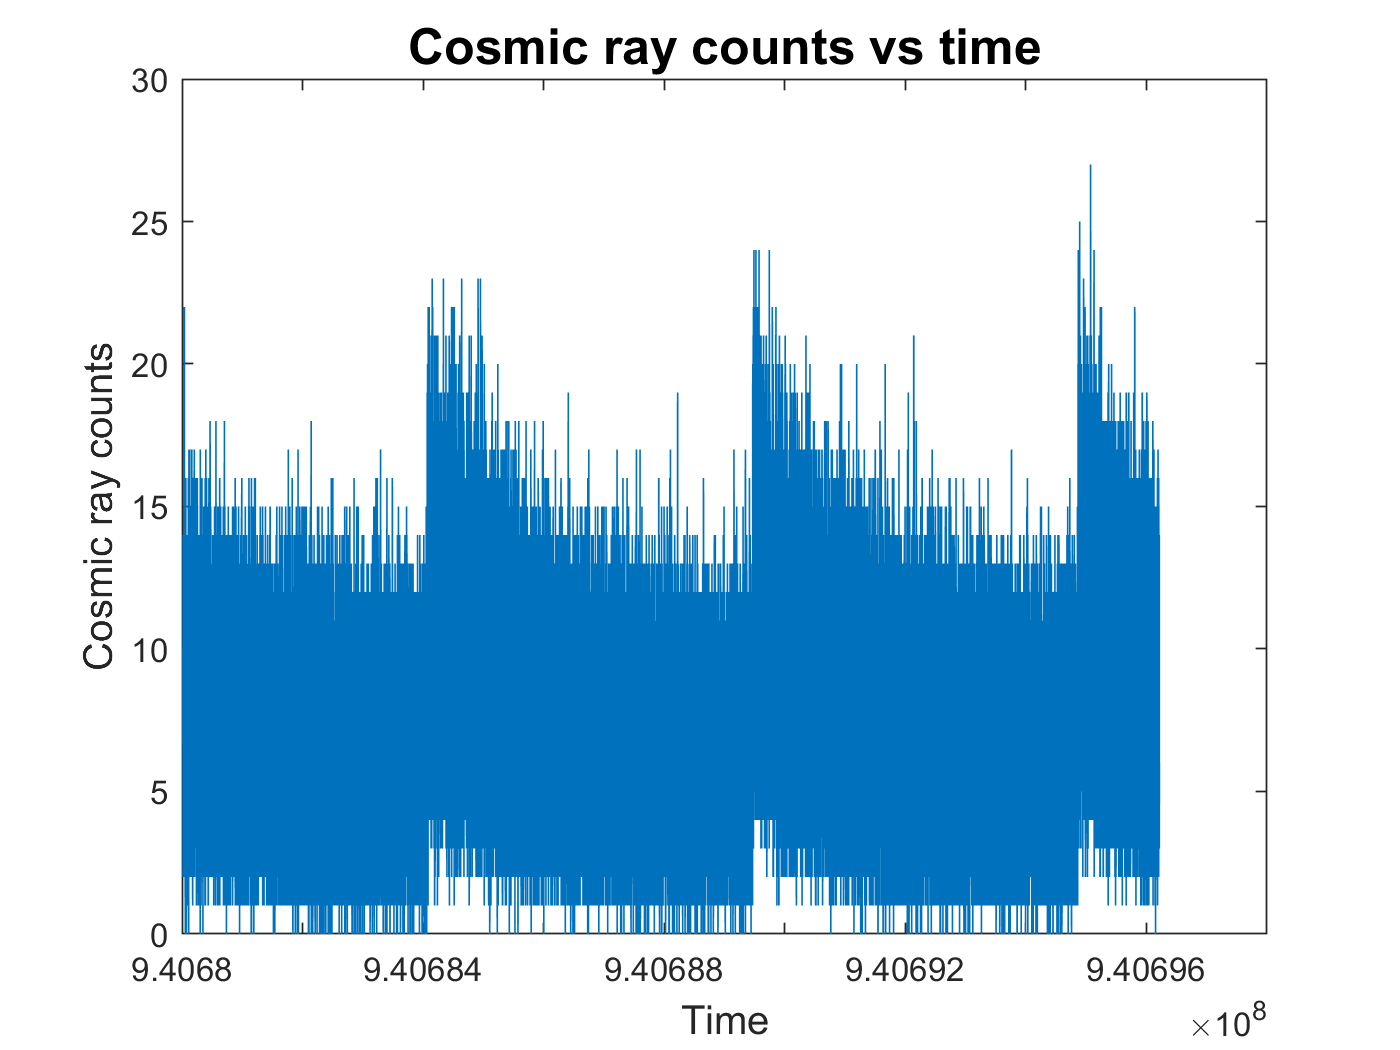

plot(mydata(1:54000*3,1),mydata(1:54000*3,4));
title('Cosmic ray counts vs time','FontSize',15)
xlabel('Time','FontSize',12)
ylabel('Cosmic ray counts','FontSize',12)

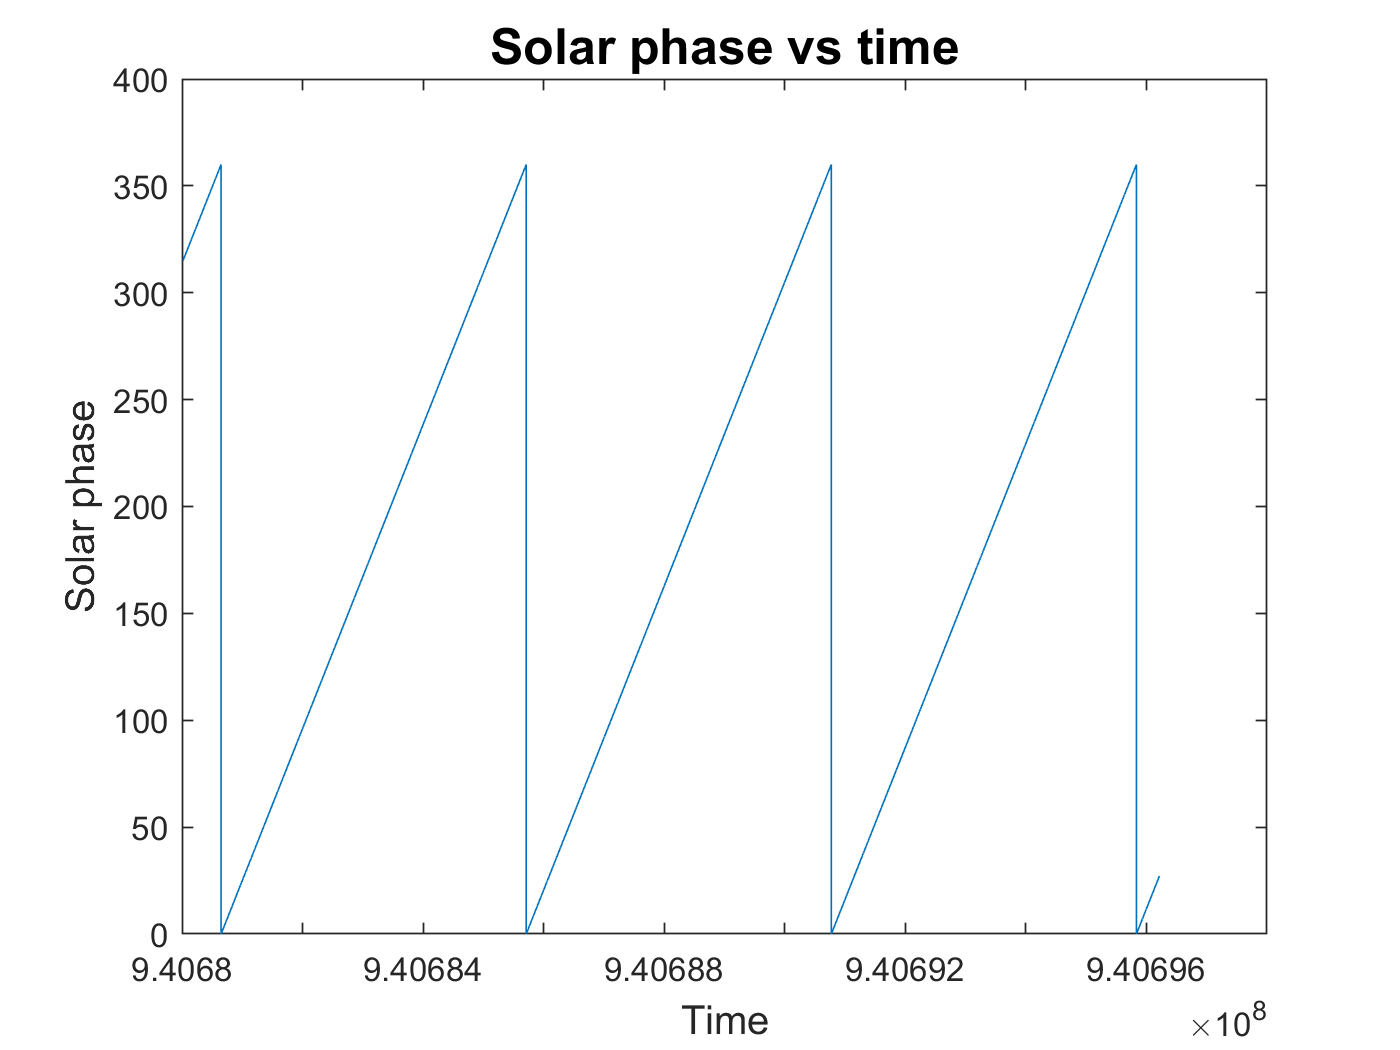


plot(mydata(1:54000*3,1),mydata(1:54000*3,2));
title('Solar phase vs time','FontSize',15)
xlabel('Time','FontSize',12)
ylabel('Solar phase','FontSize',12)

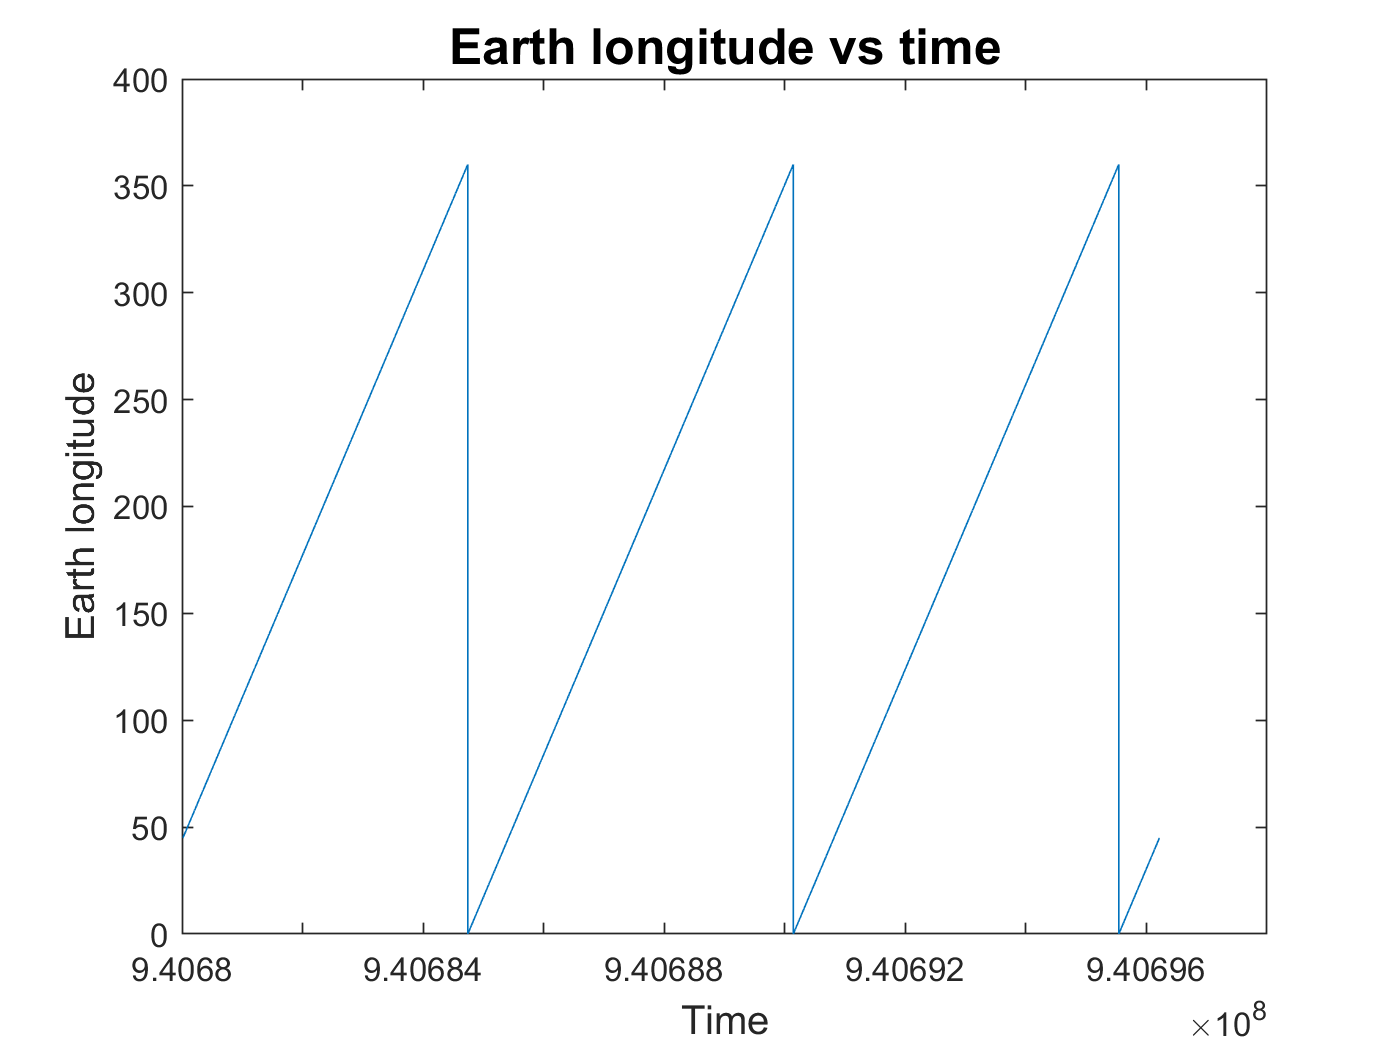


plot(mydata(1:54000*3,1),mydata(1:54000*3,3));
title('Earth longitude vs time','FontSize',15)
xlabel('Time','FontSize',12)
ylabel('Earth longitude','FontSize',12)

The plot of cosmic rays versus time clearly shows that the cosmic ray counts varies with time. The variation of cosmic ray is periodic and the period is about the same as the orbital period of the satellite.The cosmic ray counts seem to have a exponential decay pattern overtime. 

Although I discovered that the counts varies in a small time scale, it is hard to convince ourselves that the whole data set has the consistent periodic variation that we discovered. Therefore, I decided to divid(**divide)** the data set into several windows. Each window contains 54000 data points(one orbital period of satellite). I will average the cosmic ray counts of all the windows and see if the exponential decay pattern still holds. The code below will average the cosmic ray counts over all the windows and plot the final result. I started with finding the data point that correspond to the highest cosmic ray counts (the peak of the exponential decay) and set that point as the beginning of the first window. The end of the first window is set to (54000-1) points after the first point of the window. By dividing my windows this way, there will be 54000 points in each window and we end up have 479 windows accross the entire data set. 

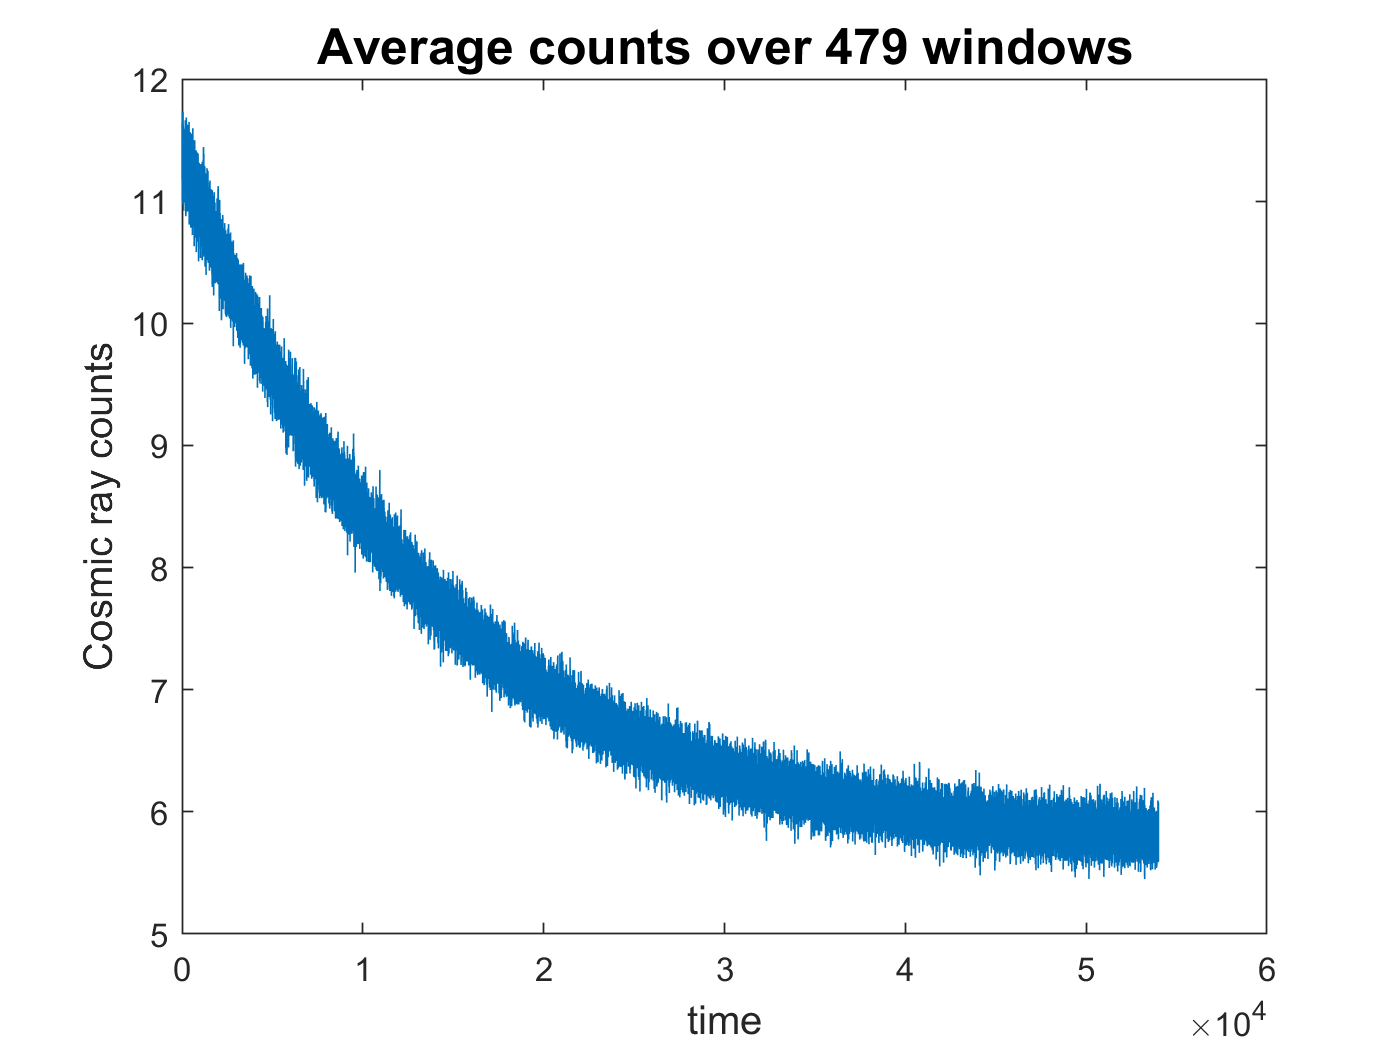

%%This is where I average the data
%Start with finding window1. The first point of the actually data does not
%correspond to the peak of the exponential decay. So I locate which
%point of the actual data correspond to the peak.
% It seems that data point 40500 is where the peak is. Therefore, window1 is from point 40500 to 40500+54000. 

%Define sum as window1 first and get to the loop
sum = mydata(40500:40500+54000*1-1,4);

%The loop runs 478 times because we only have 479 windows if the first
%window starts at data point number 40500. And we perform the sum for 478
%times. (There are 480 windows in the data set by the way.)
for i = 1:length(mydata(:,1))/54000-2
    %First round of loop will sum window1 with window2.Round 2 will add
    %window3 in. At the end of the loop, all the windows will be summed
    %together.
    window = mydata(1+40500+54000*i:40500+54000*(i+1),4);
    sum = window+sum;
end 
%Divide the sum of all windows by 479 because we summed over 479 windows
data_avg = sum/(length(mydata(:,1))/54000-1);
%Plot it to see how it looks
plot(data_avg)
title('Average counts over 479 windows',"FontSize",15)
xlabel('time',"FontSize",12)
ylabel('Cosmic ray counts',"FontSize",12)

(Note: The average cosmic ray counts over 479 windows represent the cosmic ray counts we expect to measure within 100 milisecond over the entire orbital period. This information is important because we will use the averaged cosmic ray counts over 479 windows to model the time dependnent probability distribution of cosmic ray counts)

After the average counts over 479 windows was calculated and ploted, we can see that the counts has a exponential decay pattern overtime. It suggests that the periodic exponential decay pattern is consistent over the entire data set. Note that the plot has a lot of "wiggles" because the acutuall **(actual) **measurement of counts fluctuate due to the instrument accuracy and other disturbance (the beauty of living in the real world). Even though the plot has wiggles, the evolution of the counts shows that we can fit the data with a exponential curve.  When we say the counts decay exponentially overtime, we are referring to the overal trend of the counts. 

The exponential decays of the counts suggest that the probability distribution function of the counts evolve overtime. If we find the pdf of cosmic ray counts within 100 milisecond period, this pdf will changes with time. Assume that the pdf of cosmic ray counts within 100 milisecond is a Poisson distribution (cosmic ray counts are discrete) with lambda = average counts within 100 milisecond, lambda evolves overtime and decay exponentially. Therefore, the threshold for "5 sigma" detection changes with time as well. 

To see how the pdf of cosmic ray counts changes overtime, we first have to create a model for the time evolution of the pdf. 

I am going to use the average cosmic ray counts I found in the previous section because it tells us what is the average cosmic ray counts we expect to measure at different time within the satellite orbiting period. Since the time evolution of cosmic ray counts is a exponential decay, we expect the cosmic ray counts as a function of time has the form: $A*e^{-\textrm{kt}} +B$, where A+B is the maximum count, k is the constant determin the rate of decay, and B is the minimum count. The work we need to do is basically finding the values for A,k,and B. Here I use matlab function "fminsearch" to find those values. The code below will find A,k, and B values and plot the curve against the average cosmic ray counts within 100 milisecond over the entire orbital period of the satellite to see how well does the model capture the time evolution of cosmic ray counts.

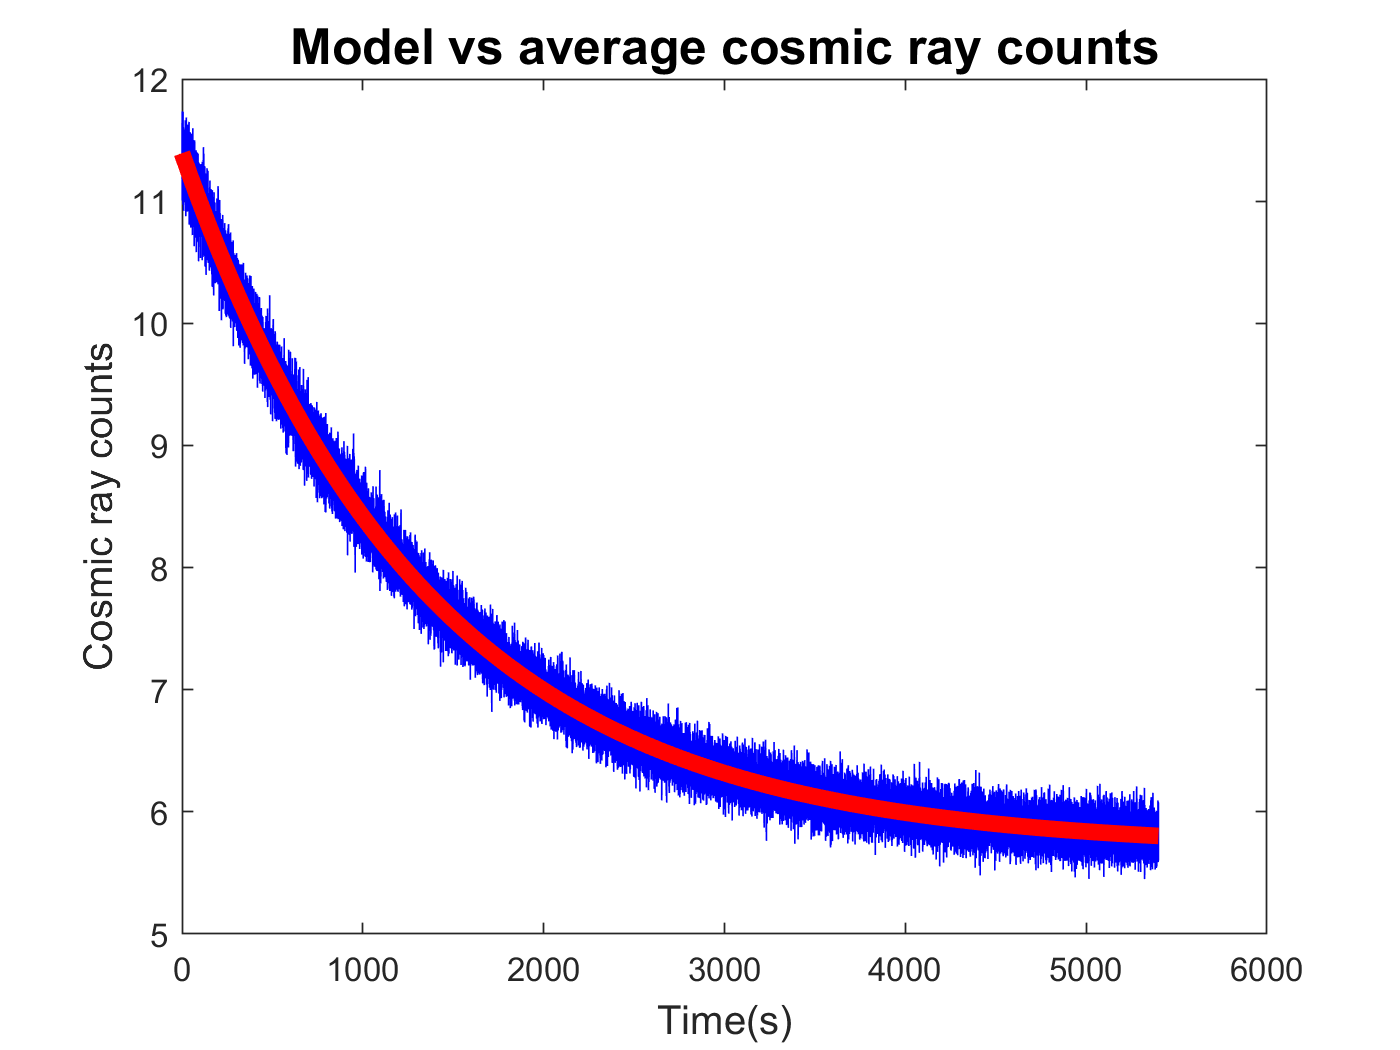

%To fit our data with a curve, we want the values of the model function f(x)
%to be as close as possible to the data we are fitting, which means
%sum(f(x)-data(x)) has to be minimized.

%Creat a function that we want to minimize with fminsearch
t = 0:0.1:5399.9;
fun = @(v) norm(v(1)*exp(-v(2)*t')+v(3).*ones(length(t),1)-data_avg,2);
%Give initial guess to fmincon
v0 = [11 1 6];
V = fminsearch(fun,v0);

plot(t,data_avg,'Color',[0,0,1])
hold on
plot(t,V(1)*exp(-V(2)*t')+V(3),'LineWidth',5,'Color',[1,0,0])
title('Model vs average cosmic ray counts','FontSize',15)
ylabel('Cosmic ray counts',"FontSize",12)
xlabel('Time(s)',"FontSize",12)

After using fminsearch to fit the data, I found the values for A,k,and B. I ploted **(plotted)** the function against the average cosmic ray counts and it seems that the curve fit the data pretty well. The model for the average cosmic ray counts will be the exponential function that was found with fminsearch. With the model, we can then estimate the average cosmic ray counts that we expect to measure within 100 milisecond at different time of the satellite orbiting period. The wording of this statement may be a little bit confusing, but allow me to explain this in more details. The **(that?) **each data point of cosmic ray counts in the data set is the cosmic ray counts measured within 100 milisecond. When we divid **(divide) **the data set into several windows where each window contains the measurement over 1 orbital period of the satellite and average the measurements of all the windows, we are basically averaging the cosmic ray counts within 100 milisecond measured at different point of the orbital period (for example the beginning and the middle of the period), over multiple orbiting period. I am not sure if this explainaltion is making things more confusing but it is the details of the statement I made earlier.

Now we have the model for the average cosmic ray counts we expect to measure at every points of the satellite orbiting period. We can calculate the 5 sigma threshold for every point of the orbiting period. At every point of the orbiting period, the background distribution, the cosmic ray counts probability distribution is a Poisson distribution. Instead of being constant across every point of the orbiting period, the lambda of the Poisson distribution is different at different point of the orbiting period. This sounds like a headach but luckily we now how the "lambda" evolves with time. The values of lambda decay exponentially with time. If the satellite captured a signal at the middle of its orbiting period, we can use the model to estimate the lambda of the Poisson distribution and calculate the sigma that correspond to the signal and evaluate its significance. Since we have the lambda for every point of the orbiting period, we can calculate the 5 sigma threshold at every point of the orbiting period. The code below will calculate the 5 sigma threshold at every point of the orbiting period. Finding the point correspond to 5 sigma is basically finding the number of counts X where the probability of getting as many counts or more counts than X from the background is 5 sigma(1/3.5 million).

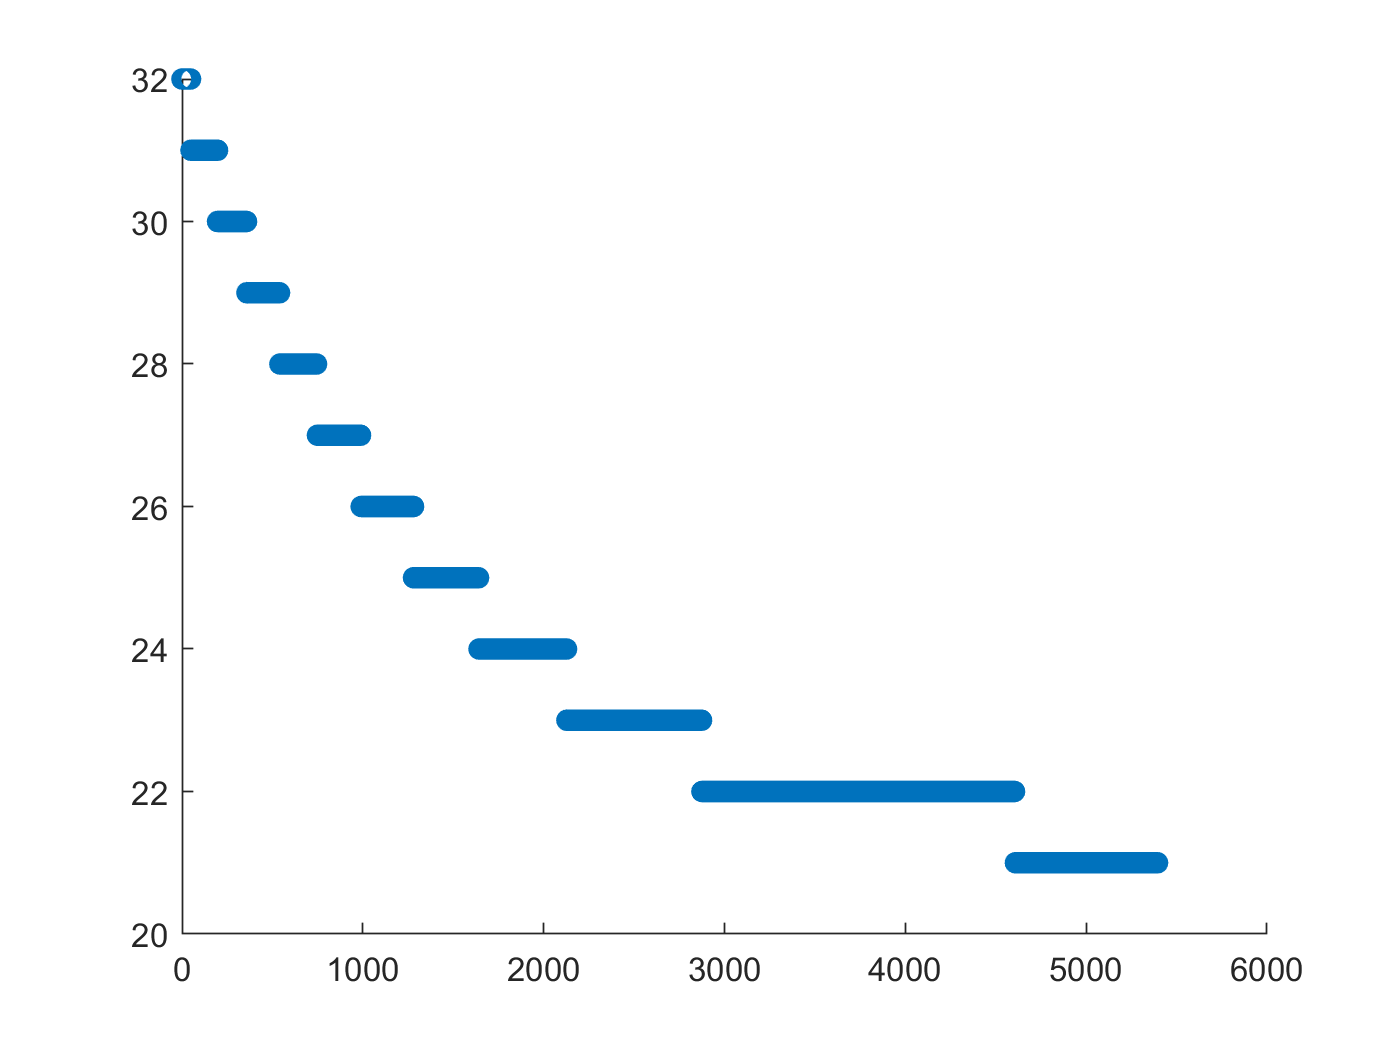

p = 1/3.5e6;
lambda = V(1)*exp(-V(2)*t')+V(3);
sigma_5 = icdf('Poisson',1-p,lambda);
hold off

scatter(t,sigma_5)

The 5 sigma threshold was calculated and plotted. As we can see in the plot, the threshold decreases with time. This is not surprising because we know that the average cosmic ray counts decreases as the satellite gets further into its orbiting period. An interesting feature of the graph is its steps look. It suggests that the threshold does not vary much between adjacent points in certain sections but shifts suddenly when we move to different section. 

After calculating 5 sigma threshold at different point of the orbiting period, we can now determine the significance of the signal that we measure at any given point of the satellite orbiting period. The thing I have to mention is that I define the beginning of the orbiting period to be the point where the average cosmic ray counts is the highest because it is easier to make the model. The actual location of the satellite may not be at 0 degree of Earth longitude. However, it is easy to find the physical location of the satellite that correspond to the "beginning" of the orbital period that we define. We can simply find the entry of the data point that correspond to the "beginning" of the orbital period in the data set and find the Earth longitude and gps time that shares the same entry. In that case, we can inform ourselves where the satellite physically located and what gps time does it correspond to.  

**Problem 2**

In this problem we are going to look at a stack of telescope images .The a stack of 10 square images, each 200 pixels on a side.

Assume that these 10 images were taken from a stationary telescope that aims at the same direction, the background should not change with time too much. 

Ar **(A) **good way to validate that background does not change with time is to plot the images on the histogram and examine what does the distribution of the intensity on each pixel look like. The code below will plot all 10 images on the histogram.

I = h5read("images.h5",'/imagestack');
for i = 1:10
    Img(:,:) = I(i,:,:); %when i ran the code it broke here, it looks like you defined I lower and i guess deleted it? but yeah i put ur function I there 
    histogram(Img)
    hold on
end
ax = gca;
ax.YScale = 'log'

ax =   Axes with properties:

             XLim: [-5.3300 50.3300]
             YLim: [1 10000]
           XScale: 'linear'
           YScale: 'log'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


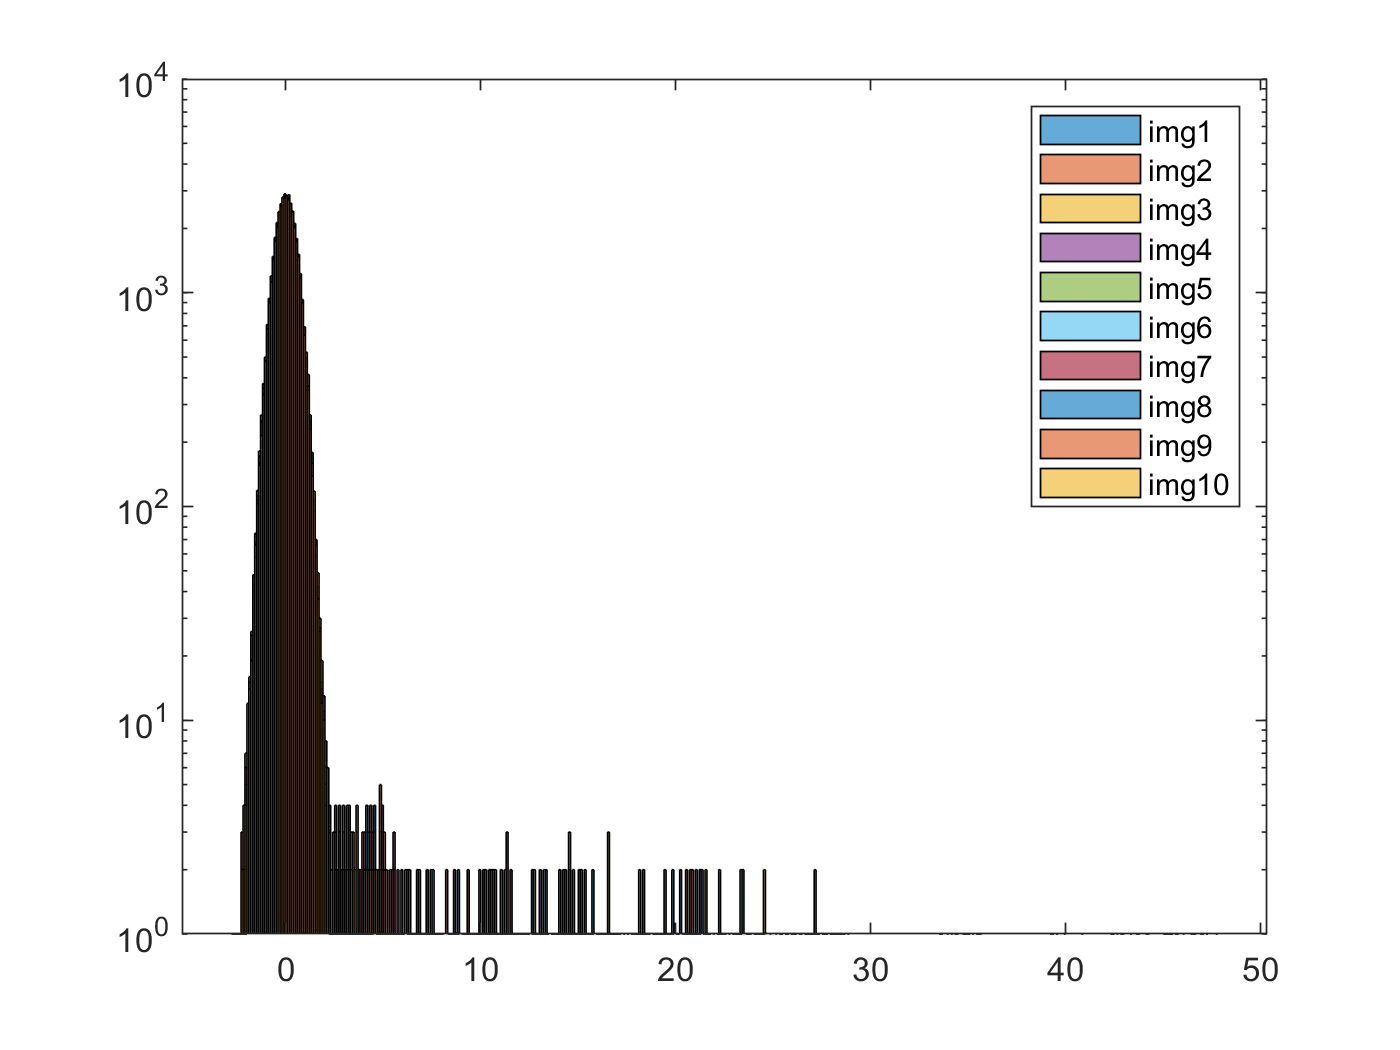

legend('img1','img2','img3','img4','img5','img6','img7','img8','img9','img10')

The histogram of 10 images show that there is a Gaussian like distribution that does not change much across different images. That could suggest that the background distribution does not vary a lot with time. However, the Gaussian like distribution in the plot does not suggest that those outliers in the plot are signal containmination because the signal from a very bright star is still part of the background but it is indeed an outlier compares to other background signal.

Since we know that background does not change much with time, if there is no other signal that containminate the background, all the images should look almost the same. To test if there is any signal containmination, we can subtract one image to another and plot the difference between 2 images. If there's very little signal containmination, the plot of the difference between 2 images should be almost black.The code below investigate the signal containmination.

clear all
close all
clc
h5disp("images.h5")

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


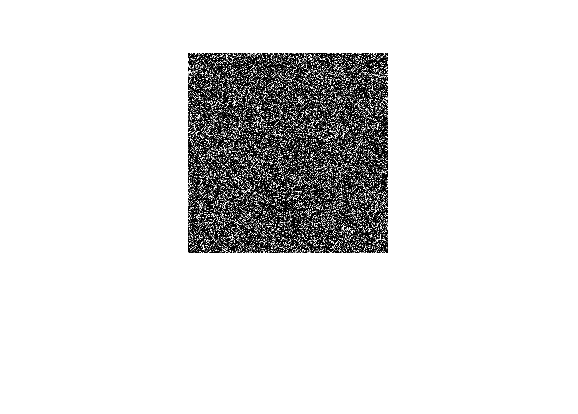

I = h5read("images.h5",'/imagestack');

Img(:,:) = I(1,:,:);
%Subtract image1 with image2
Im_diff(:,:) = I(1,:,:)-I(2,:,:);
%Plot the difference between image1 and image2
imshow(Im_diff)

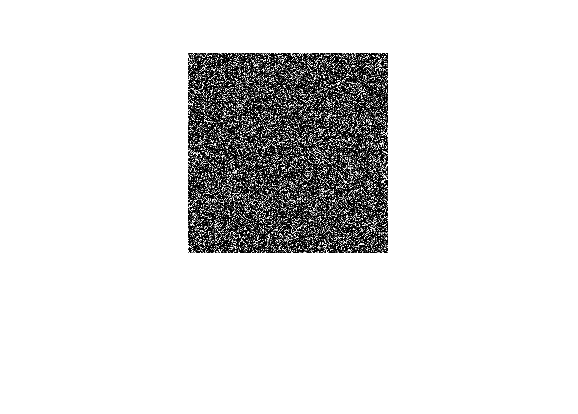

%Subtract image2 with image5
Im_diff2(:,:) = I(2,:,:)-I(5,:,:);
imshow(Im_diff2)

The difference between 2 pairs of images(image1-image2, image2-image5) were plotted. As the graphs show, the difference between these 2 pairs of image is not nearly black. In fact, there are many white spots in those 2 images, which means that there are signal containmination in the 10 images taken by the telescope. 

If we only look at one of the 10 images, it is hard to isolate the background from the random noise signal. However, since we assume that the background for these 10 images are basically the same, we can take the average of these 10 images to attenuate the random noise.Since the random noise signal does not appear in the same location consistently, and the background is constant, when taking the sum over 10 images will make the background 10 times stronger while the noise signals that do not appear on same pixels everytime will not be 10 times stronger. When we divide the sum of 10 images by 10 to take the average, the random noise signal will be much weaker than the background. By averaging the 10 images, we then "attenuate" the noise.The code below average the 10 images and plot it.

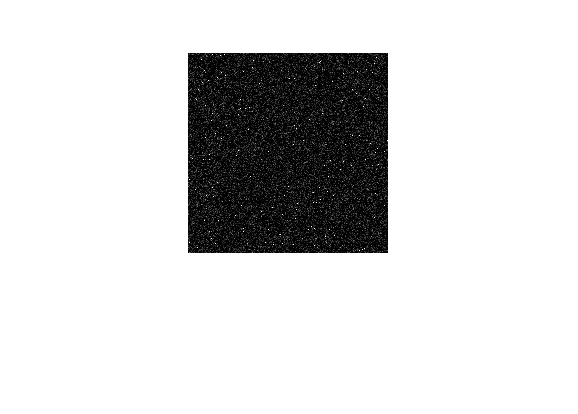


%Sum up 10 images
Im_sum = sum(I,1);
%Take the average by dividing the sum by 10
Im_avg(:,:) = Im_sum(1,:,:)/10;
%Plot the mean of 10 images
imshow(Im_avg)

The graph of the mean of the 10 images have some very bright spots on certain pixels.Those bright spots may correspond to the bright stars while dimmer spots correspond to fainter stars.  To get more information, I will plot the background distribution on a histogram with log scale on y axis.

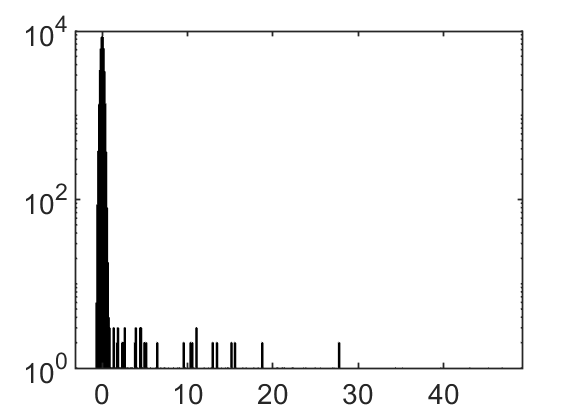

histogram(Im_avg)
ax = gca;
ax.YScale = 'log';

The plot shows that there are some outliers on the further end of the distribution. If we are hunting for the signal from a super nova, these outliers will be important because these outliers are the bright stars in our background. Since I don't want to ignore the probability of the background giving me a strong signal, I must choose a distribution that is not Gaussian. A distribution that has a longer tail like Rayleigh may be a good choice. 

To difne **(define)** the pdf of out background distribution as a Rayleigh distribution, we have to find the parameter b, where $b=\sqrt{1/2n*\sum_{i=1}^N X_i^2 }$. X is the brightness on each pixel. I will use matlab code to calculate b below and obtain the pdf for the background distribution.


b = sqrt(1/(2*length(Im_avg))*sum(Im_avg.^2,'all'));

After we determin**(determine)** the pdf for background distribution, we can hunt for the super nova. Since we know that super nova will give us a very strong signal, we are looking for the signal that passes the threshold of "5 sigma" detection. If the 5 sigma threshold is signal strength X, it means that the probability of getting a signal that is as strong or stronger than X from the background is 1/3.5 million. The first step of the super nova signal hunting is then finding the value X that corresponds to the 5 sigma thrshold. The code below will icdf to find the point X where the cdf from - infinity to point X is (1-1/3.5 million). (it is 1-1/3.5 million because icdf integrate pdf from the left but we actually want to integrate the pdf from the right)

p = 1-1/3.5e6;
X = icdf('Rayleigh',p,b);

X is found to be 45.9287. It means that the brightness on a pixel has to be greater than or equal to 45.9287 to be claimed as a super nova detection. 

Further discussion:

If we are hunting for a faint star today, Gaussian distribution will be a good choice for the pdf of background distribution because we are hunting for weak signals. When we are hunting for weak signals and the background distribution has only few outliers that correspond to strong signals, that means those strong signals are at the tail end. Since we integrate the pdf from the left end when we are trying to find the probability of getting weak signals, the shape of the tail end become less important. Therefore, when we are hunting for the fiant stars(weak signals), defining background distribution as a Gaussian is a good enough approximation.